Only the import operation was auto-generated by MATLAB on 11-Aug-2023 21:45:28

#### Set up the Import Options and import the data

clearvars,clc
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Nucleus", "Z", "A", "BAEXPMeV"];
opts.VariableTypes = ["string", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Nucleus", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Nucleus", "EmptyFieldRule", "auto");

% Import the data
tbl = readtable("C:\Users\Samiha\Documents\MATLAB\binding_energy_per_nucleon.csv", opts);

#### Convert to output type

Nucleus = tbl.Nucleus;  %name of the isotopes
Z = tbl.Z;              %atomic number/proton number/electron number
A = tbl.A;              %atomic mass number/N+P/
BEPA = tbl.BAEXPMeV;    %binding energy per nucleon

#### Clear temporary variables

clear opts

## 1(b)Semi-empirical mass formula

The semi-empirical mass formula that states the binding energy is


$$B(A,Z)=a_vA-a_sA^{2/3}-a_c \frac{Z(Z-1)}{A^{1/3}}-a_a \frac{(N-Z)^2}{A}+\delta+\eta$$


p.s. I ignored $\eta \approx 1 to 2 MeV$(shell effects) in the calculaiotn for simplicity

### Coefficients(fitting parameters) and other constant values

Reference:Meyerhof, Walter. *Elements of Nuclear Physics*, n.d.

av=16;     %volume coefficient (per MeV)
as=18;     %surface coeff.(per MeV)
ac=0.72;   %coloumb coeff.(per MeV)
aa=23.5;   %asymmetry coeff.(per MeV)
ap=11;     %pairing coeff.(per MeV)
N=A-Z;     %No of neutrons


### Evaluating volume,surface,coulomb,asymmetry and pairing terms

%volume term
V=av.*A;
%surface term
S=-as.*A.^(2/3);
%coulomb term
C=-ac.*((Z.*(Z-1))./A.^(1/3));
%asymmetry term
As=-aa.*(((A-2*Z).^2)./A);
%pairing term
delta=(((-1).^Z+(-1).^N).*ap)./sqrt(A);
%B/A using SEMF
BEPA_Actual=(V+S+C+As+delta)./A;


### Plotting the terms of the semi-empirical mass formula

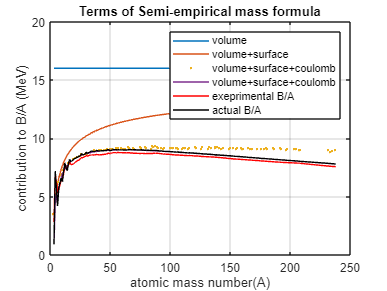

  figure(1)
  plot(A,V./A)
  axis([0 250 0 20])
  grid on
  box on
  hold on
  plot(A,(S+V)./A) 
  plot(A,(C+S+V)./A,'.')
  plot(A,(As+C+S+V)./A)
  plot(A,BEPA,'r')
  plot(A, BEPA_Actual,'k')
  xlabel('atomic mass number(A)')
  ylabel('contribution to B/A (MeV)')
  legend('volume','volume+surface','volume+surface+coulomb'...
      ,'volume+surface+coulomb','exeprimental B/A','actual B/A')
  title('Terms of Semi-empirical mass formula')

### Plotting the experimental Binding energy per nucleon vs Atomic mass number

% figure(2)
% plot(A,BEPA)
% xlabel('Atomic mass number')
% ylabel('Binding energy per nucleon,MeV')
% title('Binding energy per nucleon as a function of atomic mass number')
% legend('Experimental B/A')
% grid on 
% box on